Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Sara Rostami.D\eeg_options.m


Retrieving plugin versions from server...
Retrieving download statistics...


EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)


EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata)


EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)


EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


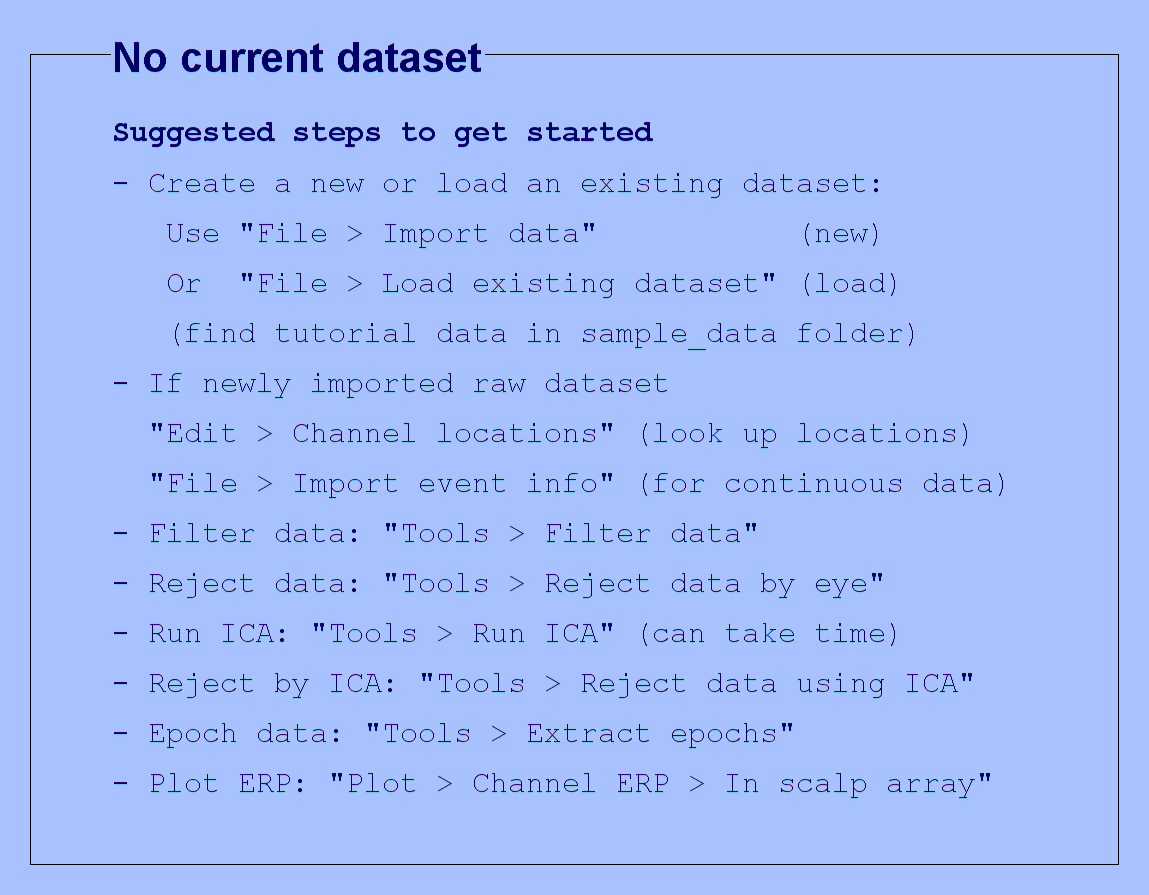

You are using the latest version of EEGLAB.


[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

## Loading the Dataset


EEG = pop_loadset('filename','eeg.set','filepath','C:\\Users\\Sara Rostami.D\\Documents\\task4_cognitive\\data\\');

pop_loadset(): loading file C:\Users\Sara Rostami.D\Documents\task4_cognitive\data\eeg.set ...
Reading float file 'C:\Users\Sara Rostami.D\Documents\task4_cognitive\data\eeg.fdt'...



[ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );

Creating a new ALLEEG dataset 1


## **Initial channel data plot**

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


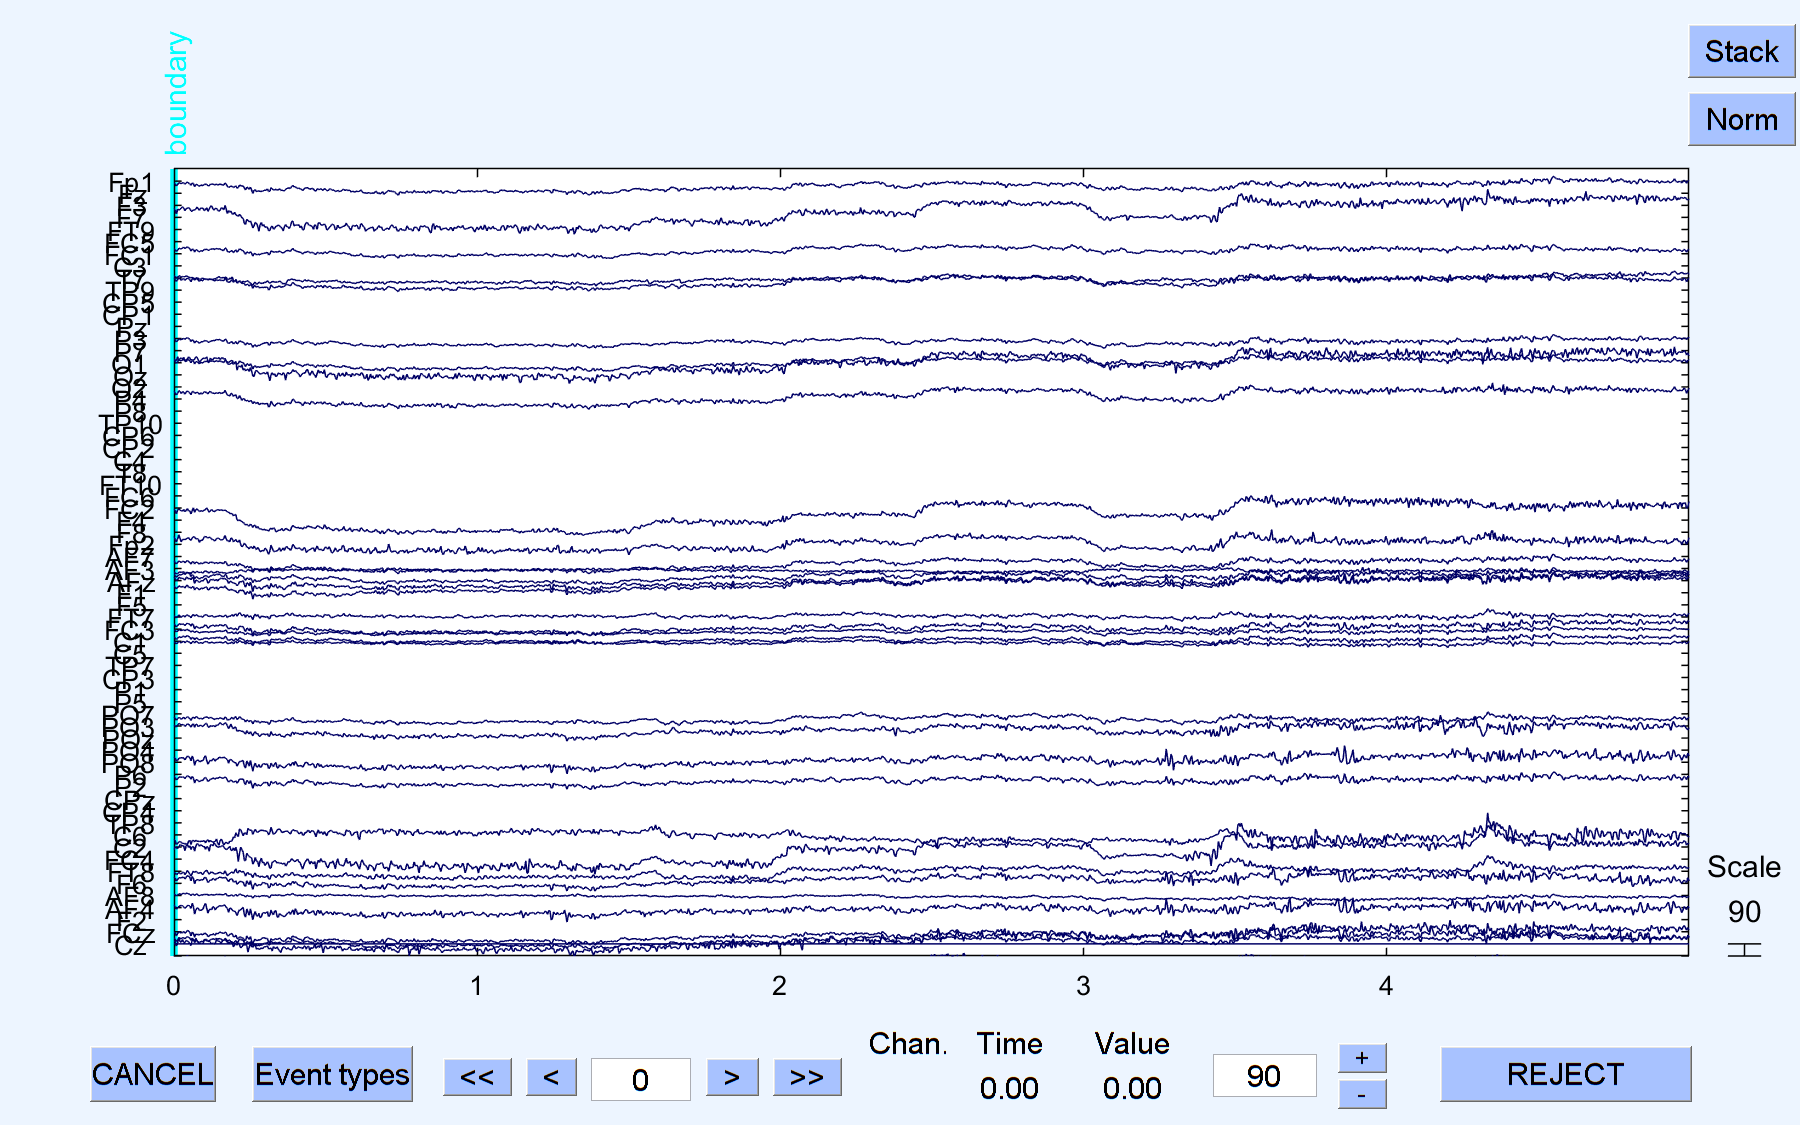


EEG = eeg_checkset( EEG );
EEG = pop_editset(EEG, 'setname', 'task4_eeg_data', 'run', []);
[ALLEEG EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
EEG = eeg_checkset( EEG );
pop_eegplot( EEG, 1, 1, 1);

## **1)**

## **Applying high-pass filter (Above 0.1Hz) **

pop_eegfiltnew() - performing 8251 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1 Hz
pop_eegfiltnew() - passband edge(s): 0.1 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.05 Hz


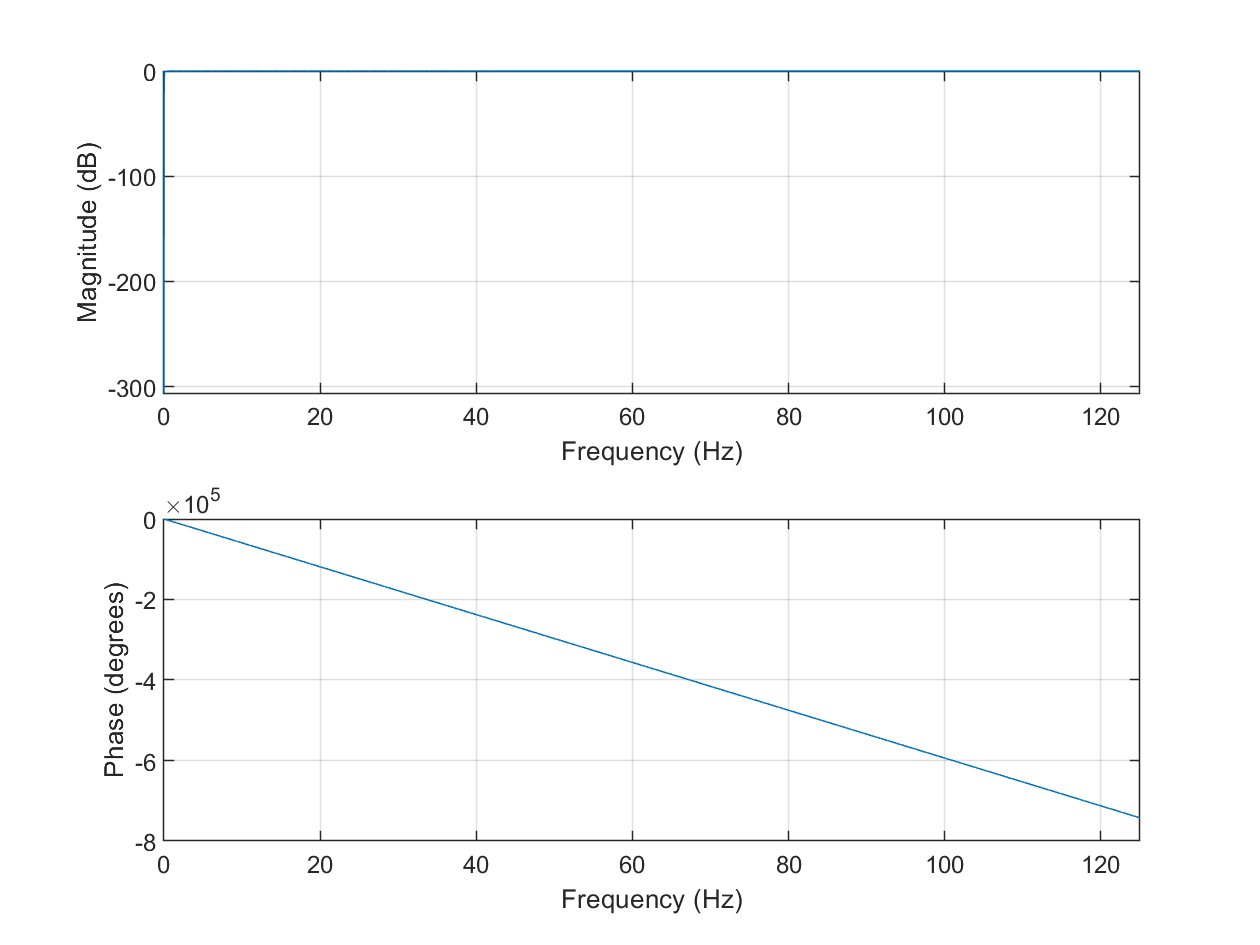

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



EEG = pop_eegfiltnew(EEG, 'locutoff',0.1,'plotfreqz',1);


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 2


## **Channel data plot (After applying high-pass filter)**

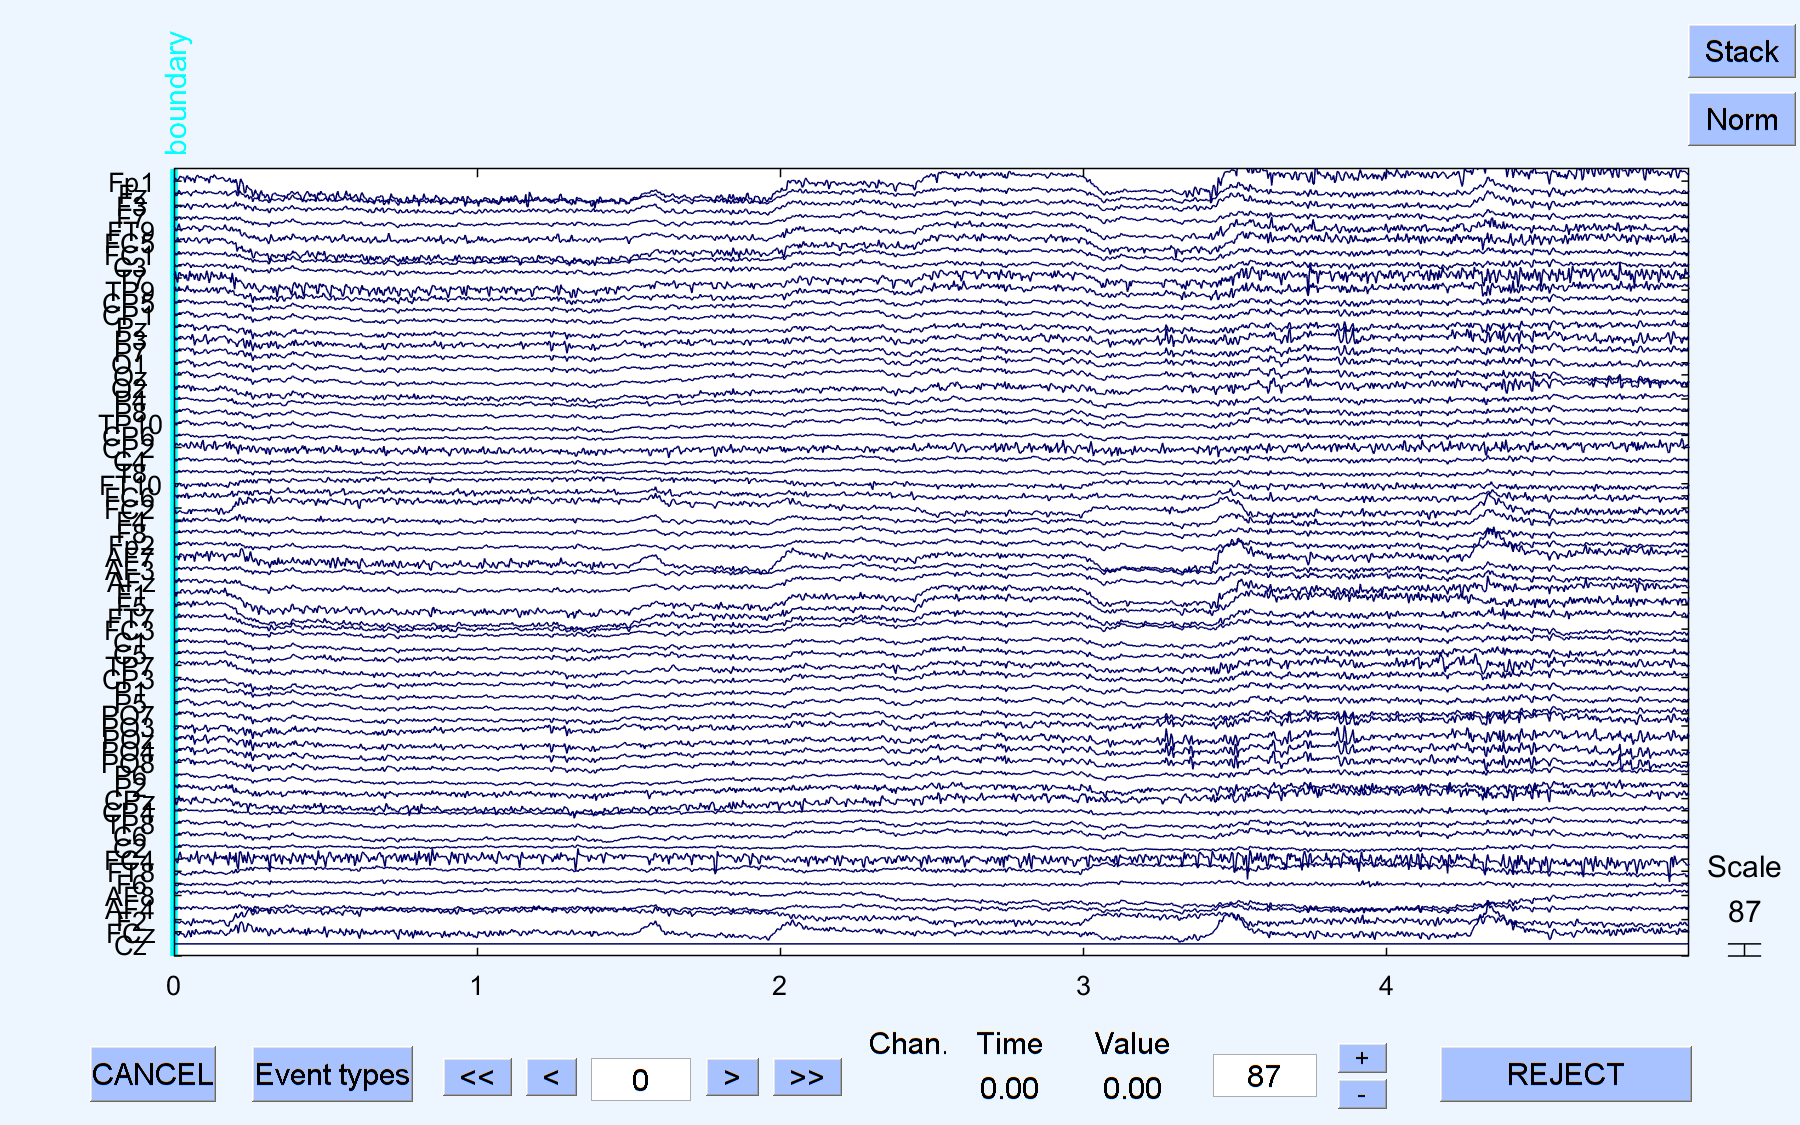

        
EEG = eeg_checkset( EEG );
pop_eegplot( EEG, 1, 1, 1);

## **Applying low-pass Filter (Below 100Hz)**

pop_eegfiltnew() - performing 35 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz


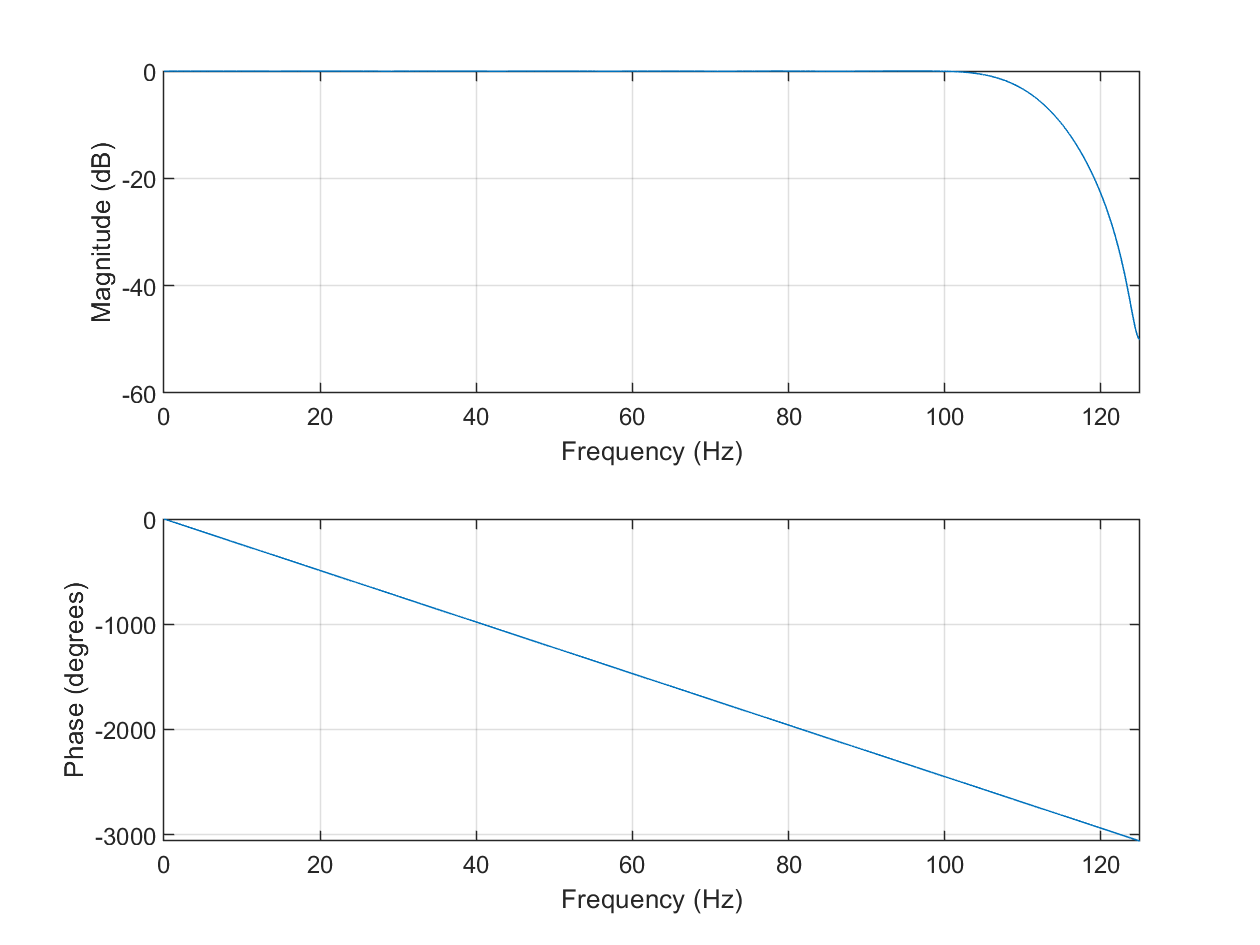

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



EEG = pop_eegfiltnew(EEG, 'hicutoff',100,'plotfreqz',1);


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 2,'gui','off'); 

Creating a new ALLEEG dataset 3


## **Channel data plot (After applying low-pass filter)**

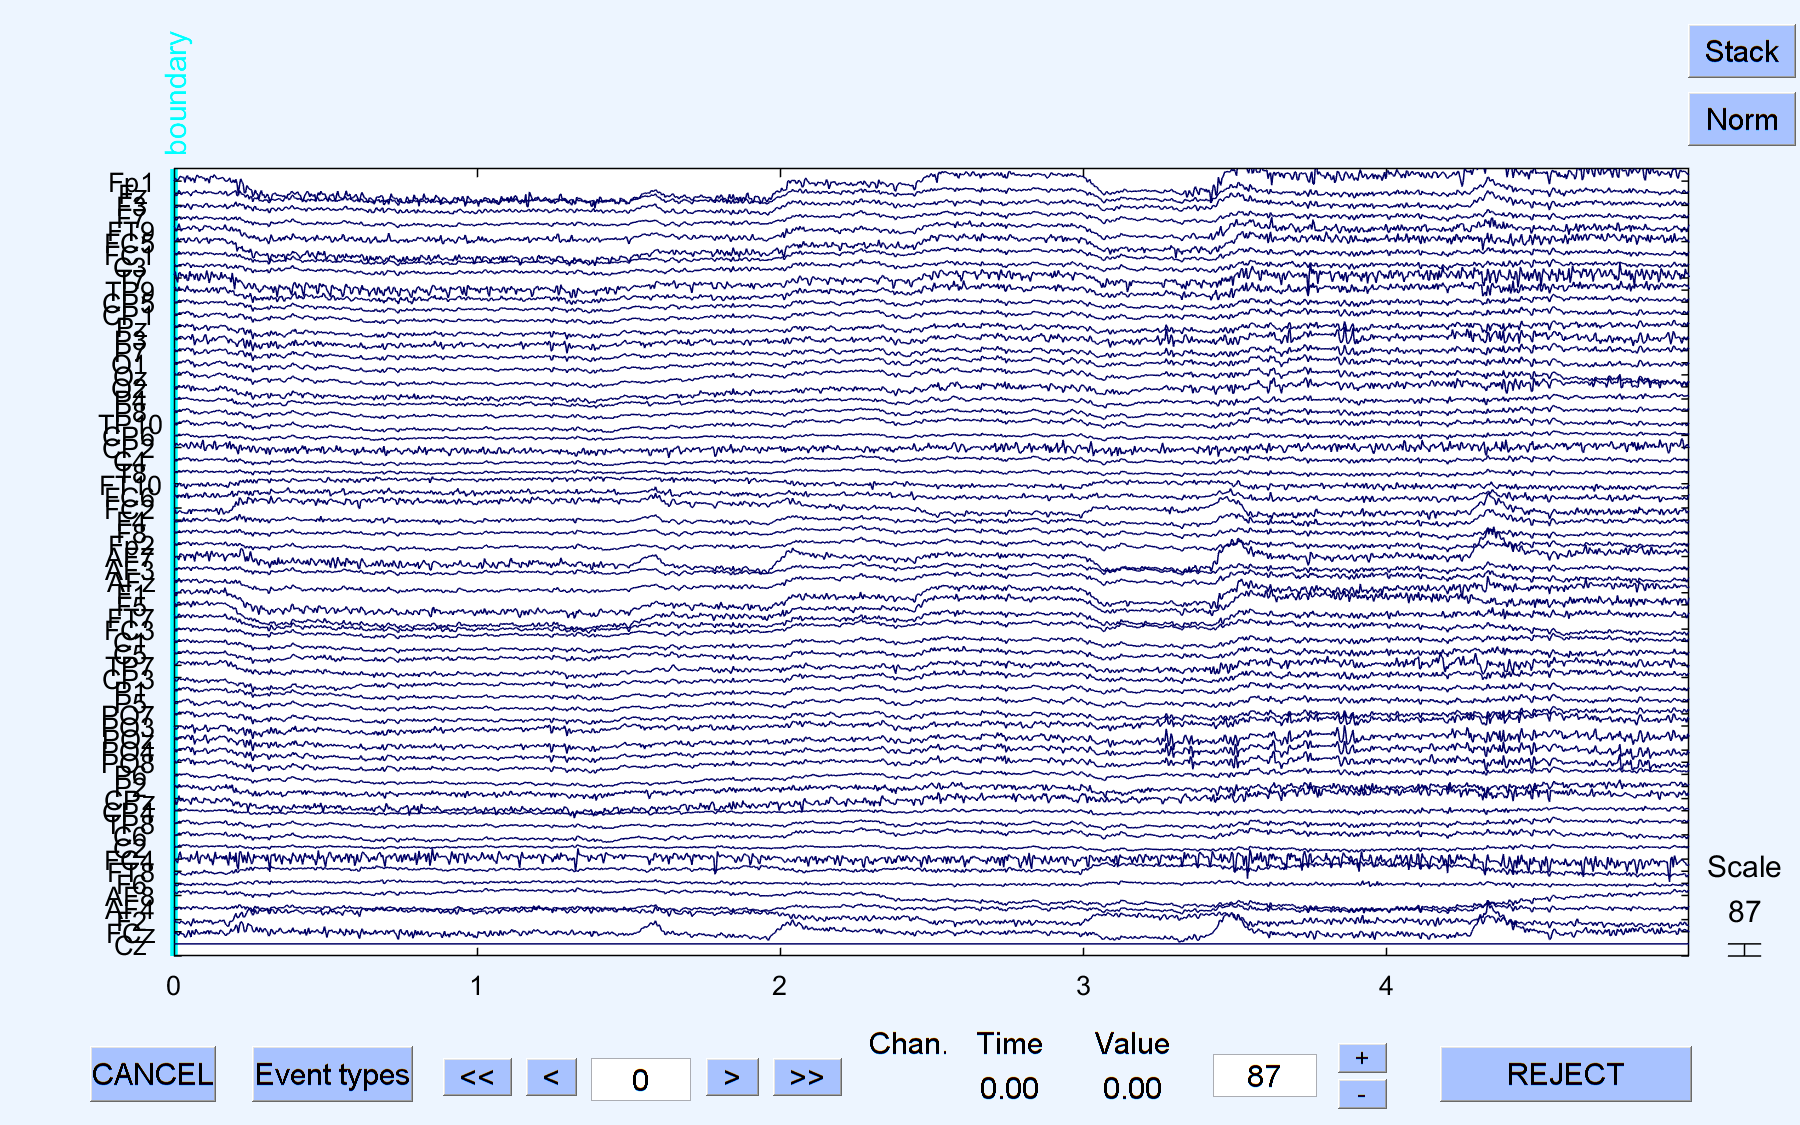


EEG = eeg_checkset( EEG );
pop_eegplot( EEG, 1, 1, 1);

## **2) Re-referencing to Average Reference**


EEG = eeg_checkset( EEG );
EEG = pop_reref( EEG, []);

Re-referencing data



[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 3,'gui','off'); 

Creating a new ALLEEG dataset 4


## **Channel Spectra (Before Re-referencing)**

Pop_spectopo: finding data discontinuities
Selecting the first 50.0% of data for analysis...
Computing spectra (window length 250; fft length: 250; overlap 0):
................................................................


Click on each trace for channel/component index


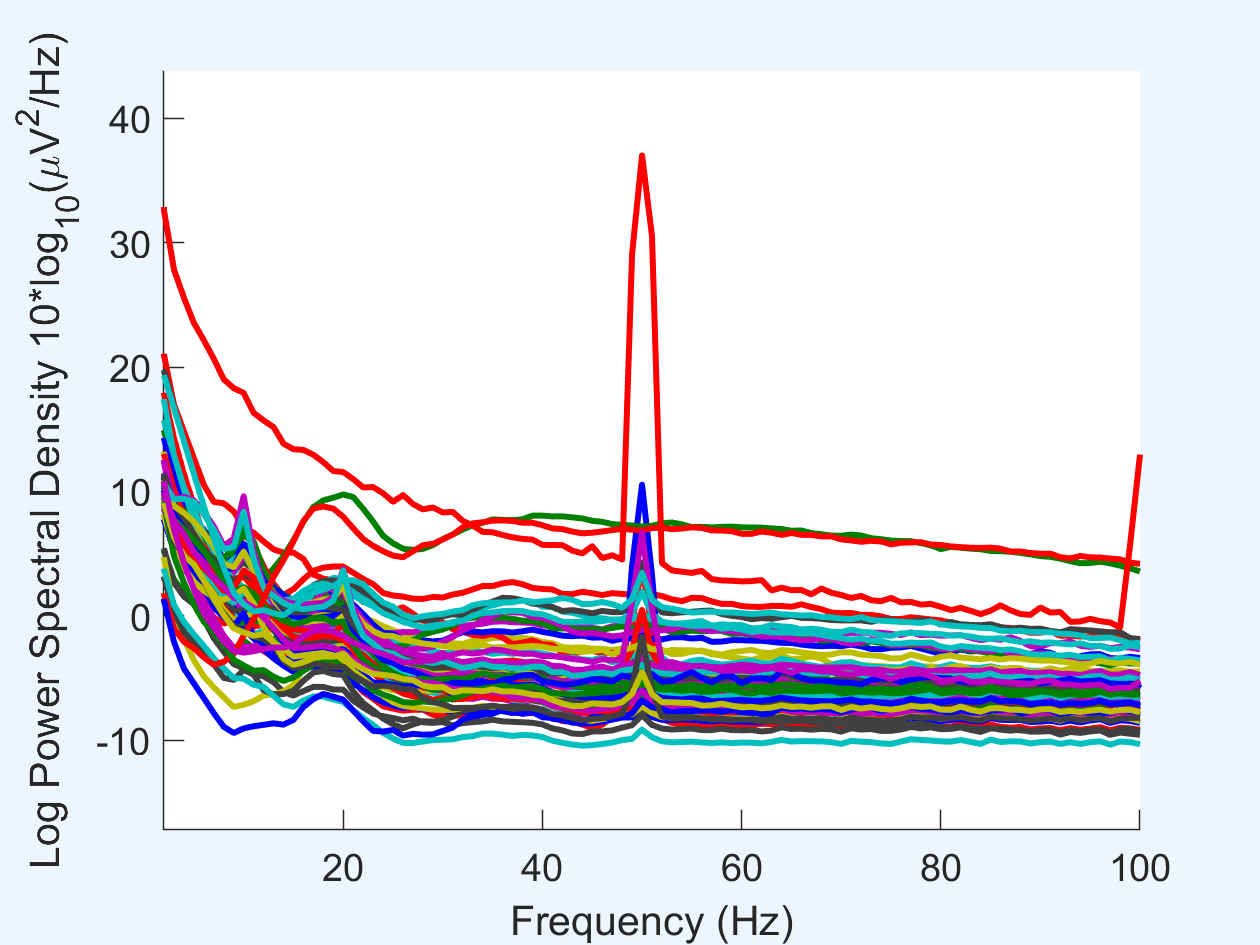


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 4,'retrieve',3,'study',0); 
EEG = eeg_checkset( EEG );
figure; pop_spectopo(EEG, 1, [0  3498476], 'EEG' , 'percent', 50, 'freqrange',[2 100],'electrodes','off');

## **Channel Spectra (After Re-referencing)**

Pop_spectopo: finding data discontinuities
Selecting the first 50.0% of data for analysis...
Computing spectra (window length 250; fft length: 250; overlap 0):
................................................................


Click on each trace for channel/component index


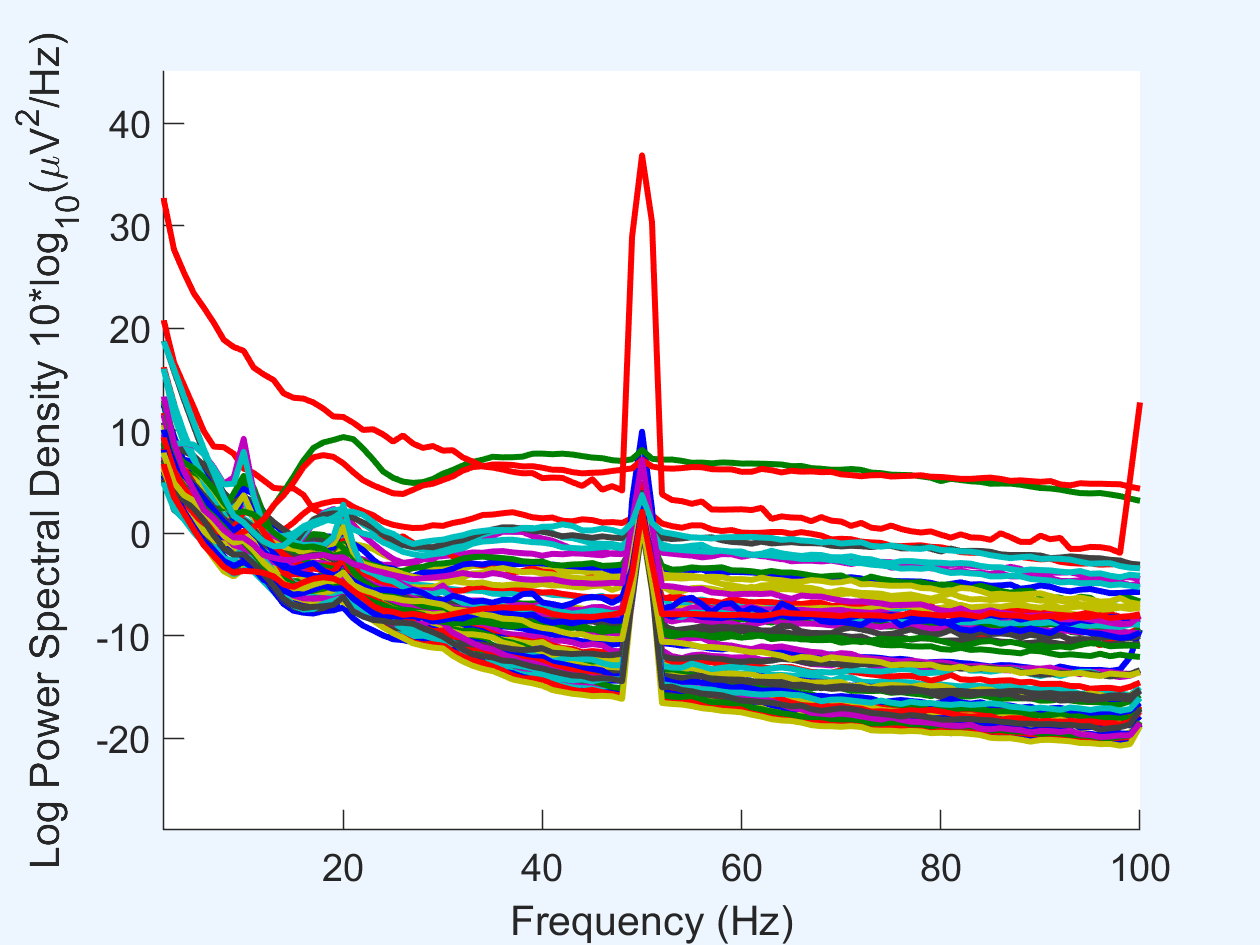


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 3,'retrieve',4,'study',0); 
EEG = eeg_checkset( EEG );
figure; pop_spectopo(EEG, 1, [0  3498476], 'EEG' , 'percent', 50, 'freqrange',[2 100],'electrodes','off');

## 3) removing line noise by Applying notch filter

pop_eegfiltnew() - performing 827 point bandstop (notch) filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [49 51] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [49.5 50.5] Hz


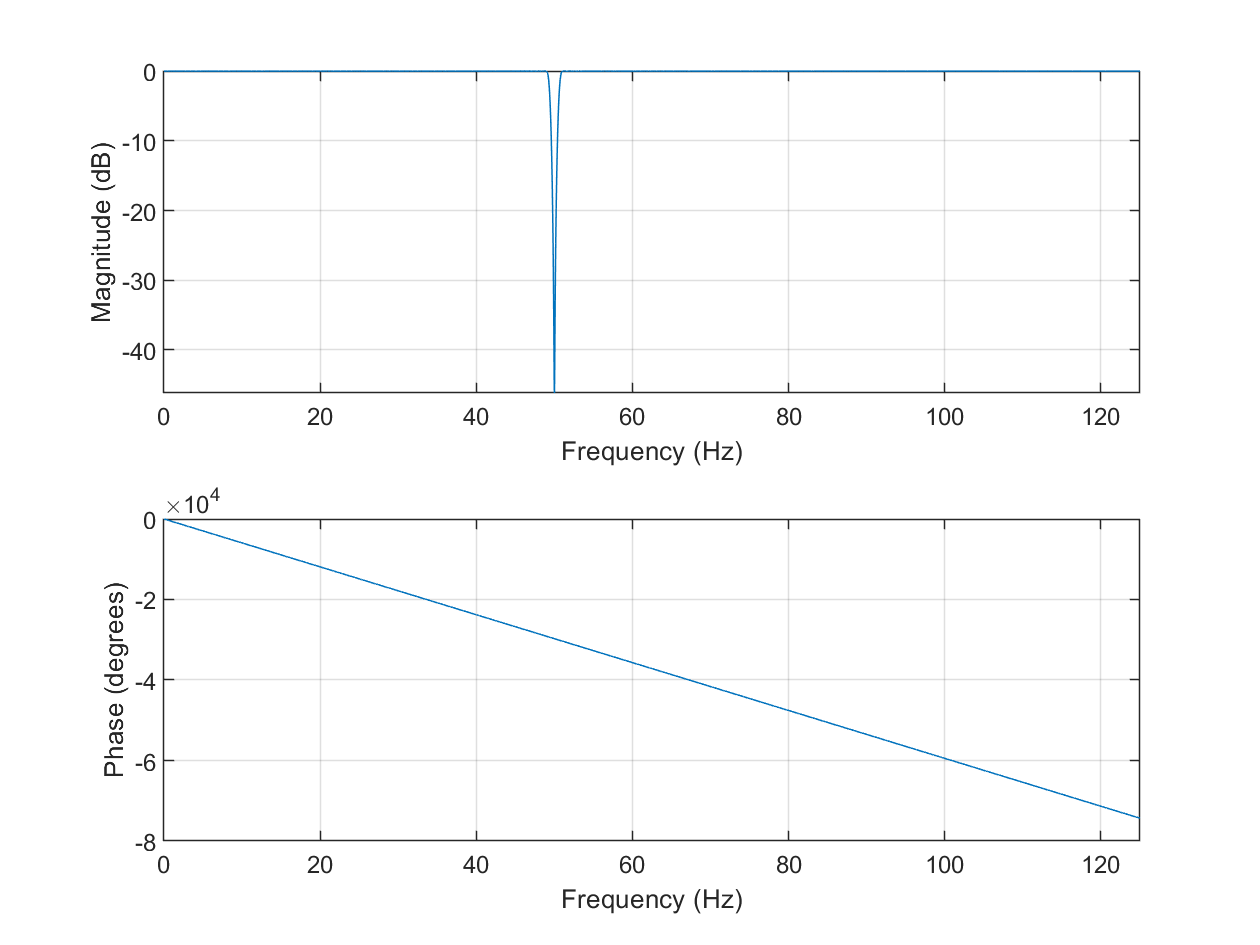

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



EEG = pop_eegfiltnew(EEG, 'locutoff',49,'hicutoff',51,'revfilt',1,'plotfreqz',1);

[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 4,'gui','off'); 

Creating a new ALLEEG dataset 5


## **Channel Spectra (after applying notch filter)**

Pop_spectopo: finding data discontinuities
Selecting the first 50.0% of data for analysis...
Computing spectra (window length 250; fft length: 250; overlap 0):
................................................................


Click on each trace for channel/component index


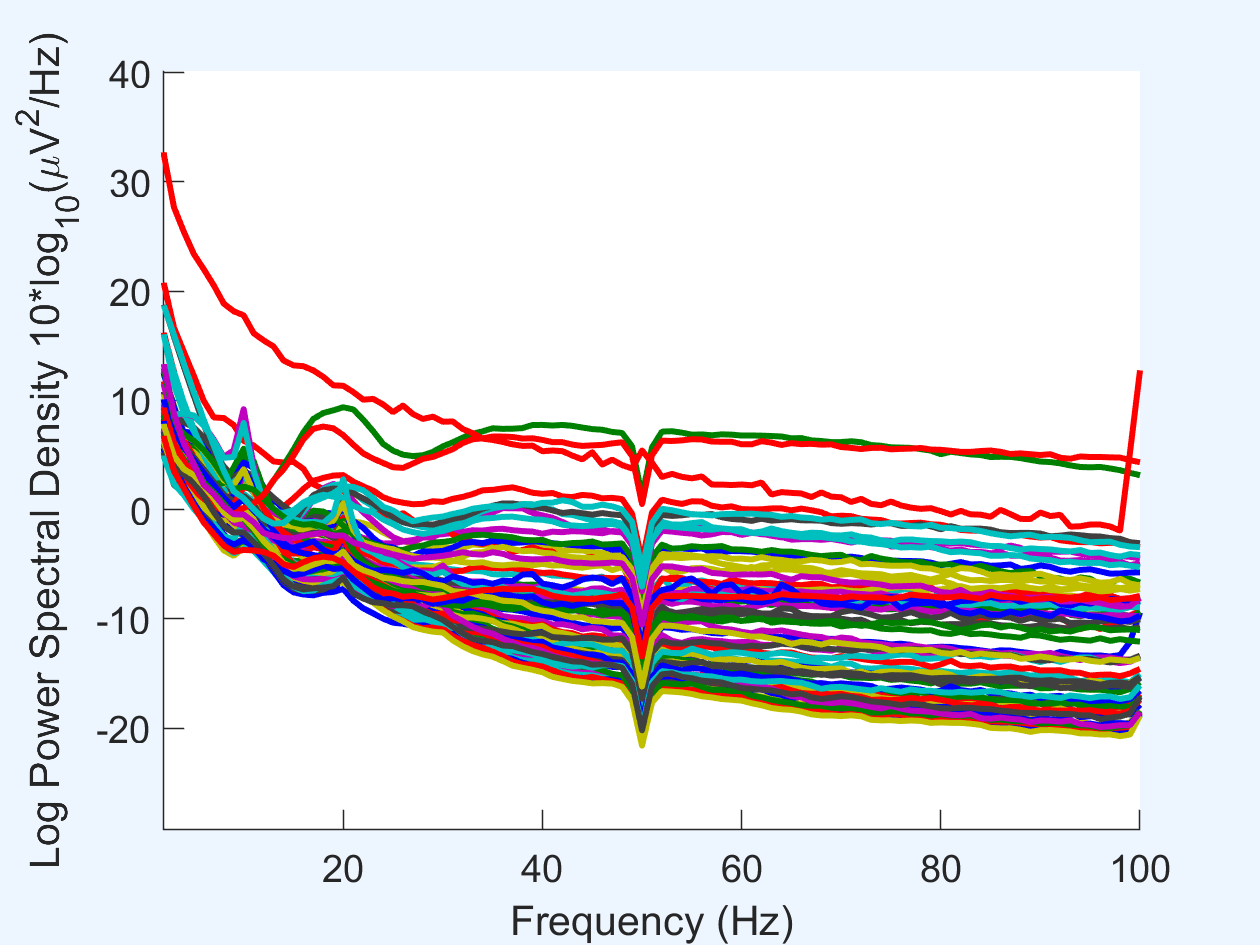


EEG = eeg_checkset( EEG );
figure; pop_spectopo(EEG, 1, [0  3498476], 'EEG' , 'percent', 50, 'freqrange',[2 100],'electrodes','off');

## 4) 

## Extracing Epoches


EEG = eeg_checkset( EEG );
EEG = pop_epoch( EEG, {  'E  1'  }, [-0.1           1], 'newname', 'task4_eeg_data epochs', 'epochinfo', 'yes');

pop_epoch():24648 epochs selected
Epoching...
pop_epoch():24648 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 5,'gui','off'); 

Creating a new ALLEEG dataset 6


## Baseline Normalize


EEG = eeg_checkset( EEG );
EEG = pop_rmbase( EEG, [-99 0] ,[]);

pop_rmbase(): Removing baseline...


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 6,'gui','off'); 

Creating a new ALLEEG dataset 7


## **Channel data plot (After Extracting Epoches & Baseline Normalization)**

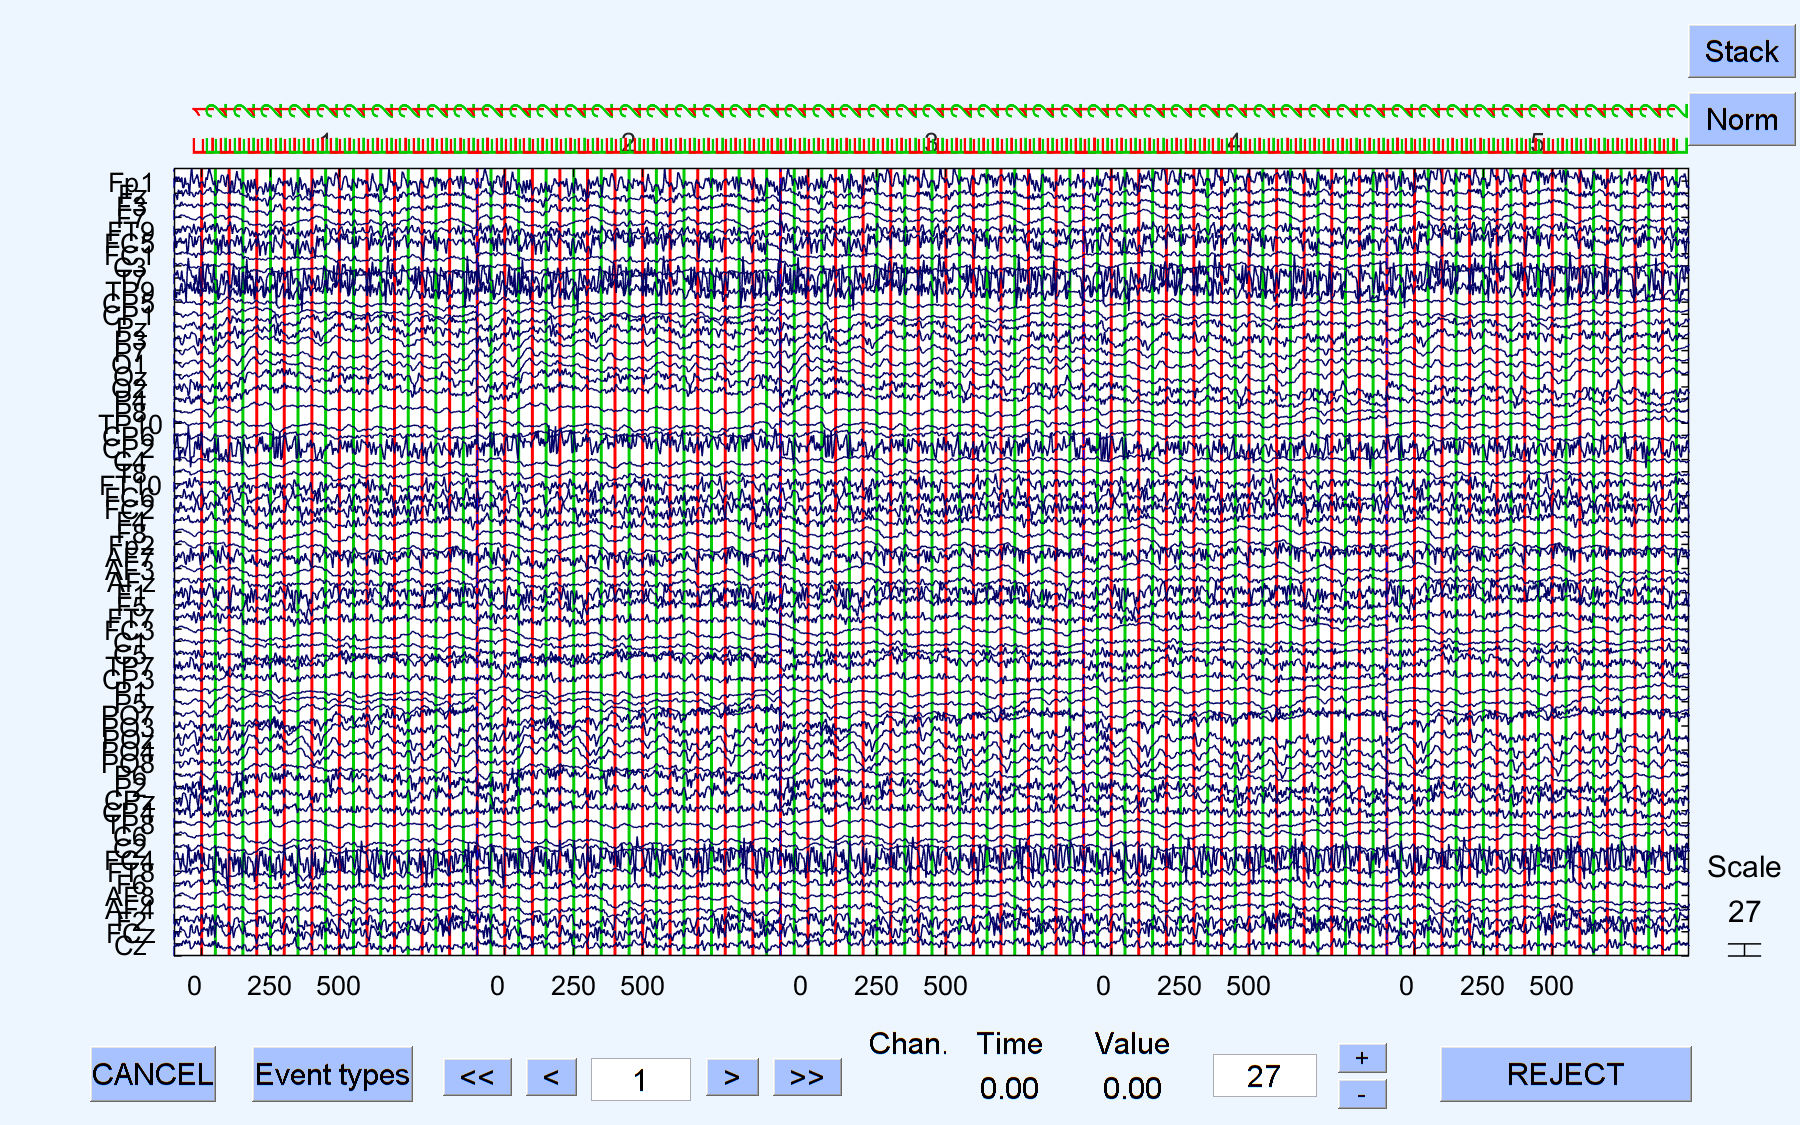


EEG = eeg_checkset( EEG );
pop_eegplot( EEG, 1, 1, 1);

## ERP data and scalp maps

Scalp maps will show latencies:  924 
                     at frames:  257 


Click on ERP waveform to show scalp map at specific latency


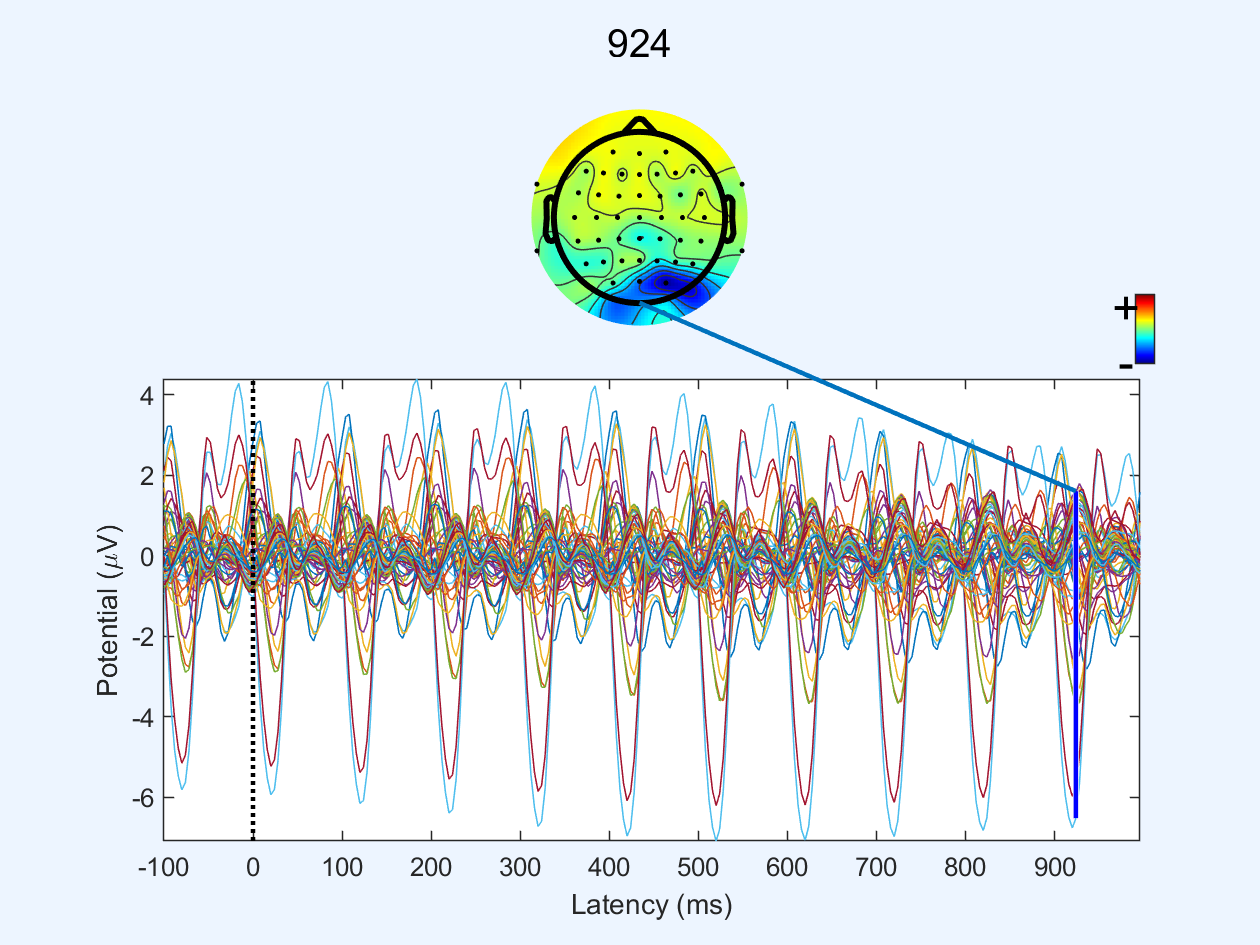


EEG = eeg_checkset( EEG );
figure; pop_timtopo(EEG, [-100  996], [NaN], 'ERP data and scalp maps of task4_eeg_data epochs');

## ERP of each channel

Plotting data using axis size [0.05,0.08]


limits: [xmin,xmax,ymin,ymax] = [-100.0 996.0 -7.09 7.09]
Plotting 1 traces of 275 frames with colors: 'b' 


trace 1: 

 1

 2

 3

 4

 5

 6

 7

 8

 9

 10

 11

 12

 13

 14

 15

 16

 17

 18

 19

 20

 21

 22

 23

 24

 25

 26

 27

 28

 29

 30

 31

 32

 33

 34

 35

 36

 37

 38

 39

 40

 41

 42

 43

 44

 45

 46

 47

 48

 49

 50

 51

 52

 53

 54

 55

 56

 57

 58

 59

 60

 61

 62

 63

 64


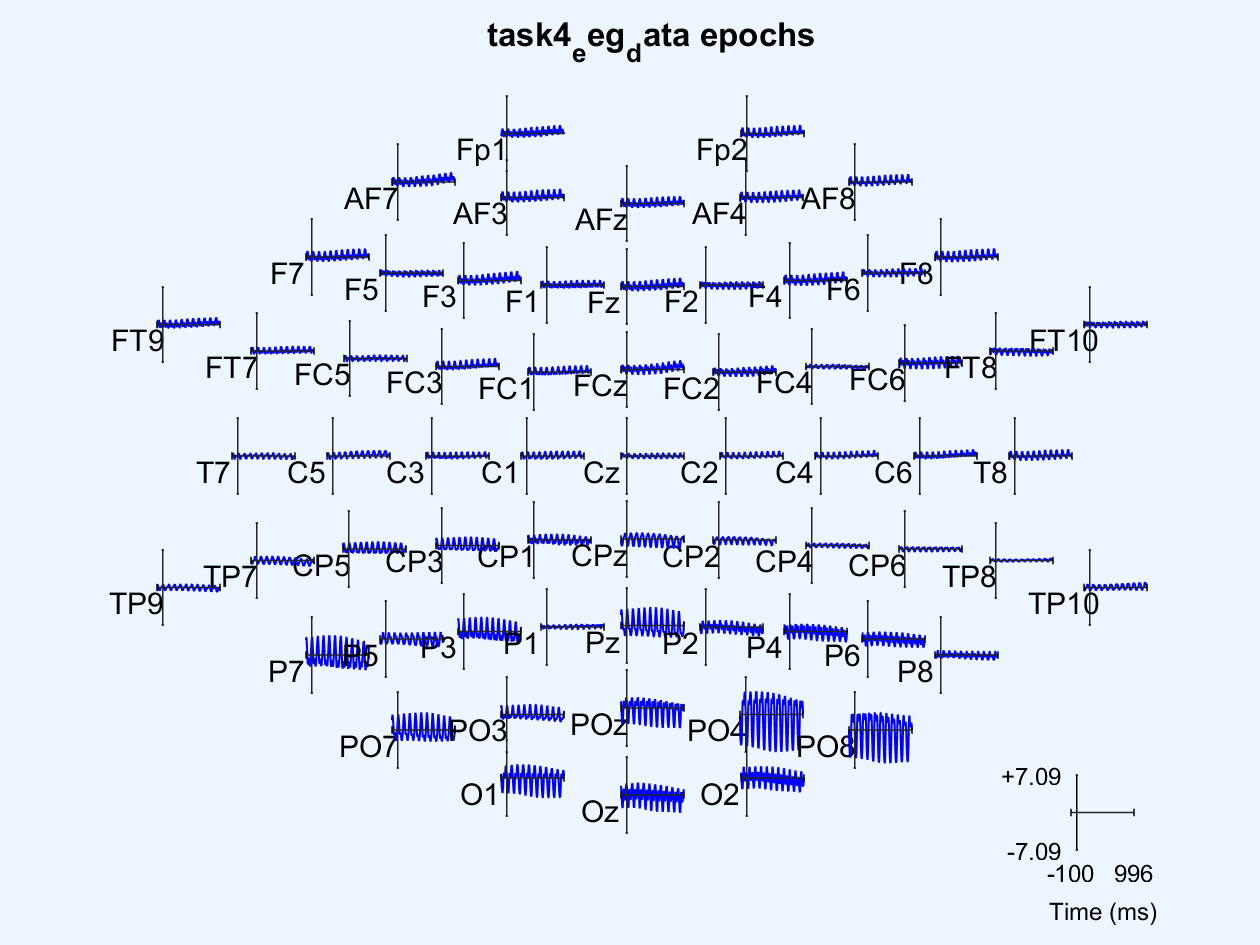


EEG = eeg_checkset( EEG );
figure; pop_plottopo(EEG, [1:64] , 'task4_eeg_data epochs', 0, 'ydir',1);

## Saving the Session Script


pop_saveh( ALLCOM, 'task4_eeg_script1.m', 'C:\Users\Sara Rostami.D\Documents\task4_cognitive\data\eeglab2022.0\');

Saving the EEGLAB session command history...


## Saving the Data Script


pop_saveh( EEG.history, 'task4_eeg_data_script1.m', 'C:\Users\Sara Rostami.D\Documents\task4_cognitive\data\eeglab2022.0\');

Saving the current EEG dataset command history...


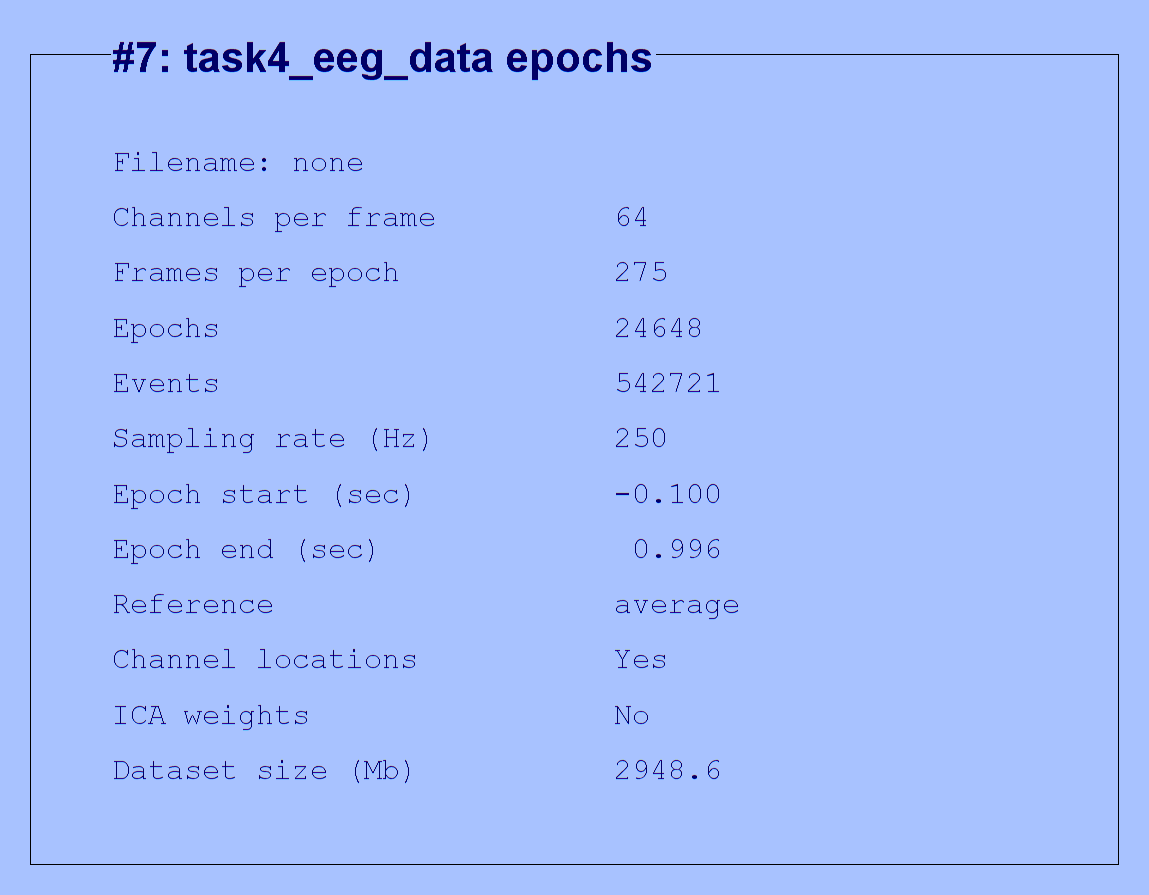

eeglab redraw;

## Saving the preprocessed Data (commented because of its huge size)


EEG = eeg_checkset( EEG );
%pop_export(EEG,'preprocessed_eeg_data','transpose','on','precision',4);

## Questions:

(a) applying high-pass filter removes sinusoidal waves with frequencies lower than 0.1Hz. these low frequencies may correspond to slow drifts. applying notch filter removes line noise which is around 50Hz in Iran & Europe. But unfortunately, at this frequency, useful brain activities also happen, so they'll be removed by notch filter. the effect of applying both of these filters on our data can be see in the outputs above.

(b) while performing cognitive tasks, other than brain activities associated with cognitive processing, there are other brain activities like regulating heartbeat, prespiration, muscle movement, etc.  that are not of importance to our research. we use referencing as a base to differentiate our useful data(signals) from these other signals that are constantly going on in the brain, regardless of the cognitive task   at hand. with baseline normalization, we try to remove signals that are associated with different thoughts and activities that are going on in the brain, especially before showing the stimulus to the participant. these thoughts are things like: what am I gonna eat today?, what is my plan for going out with my friends tomorrow?, when am I gonna finish my homework?, etc. 

(c) You can see ERP plots over each channel in the outputs above. The occipital lobe is the major visual processing centre in the brain and we can see that channels corresonding to those areas have ERPs with high frequency and amplitude.

%end of 1.1